%% ============================================================
% 4x4 RIS - ACTUAL BINARY STEERING CODEBOOK
%
% Finds all beam directions obtainable from 4 X-direction
% binary phase patterns.
%
% Each column is repeated across all 4 rows because we are
% studying steering in the X-Z plane (phi = 0 deg).
%
% HFSS unit-cell data:
% ON  = +148.922 deg
% OFF = -70.2555 deg
% ============================================================

clear;
clc;
close all;

%% ============================================================
% 1. PARAMETERS
% ============================================================

f = 2.45e9;
c = 299792458;

lambda = c/f;
k = 2*pi/lambda;

N = 4;

d = 61e-3;             % 61 mm

phaseON  = 148.9220;
phaseOFF = -70.2555;

magON  = 10^(-1.4661/20);
magOFF = 10^(-1.3114/20);

theta = -90:0.01:90;

%% ============================================================
% 2. ARRAY COORDINATES
% ============================================================

[xGrid,yGrid] = meshgrid( ...
    ((0:N-1)-(N-1)/2)*d, ...
    ((0:N-1)-(N-1)/2)*d);

x = xGrid(:);
y = yGrid(:);

%% ============================================================
% 3. ALL 16 X-DIRECTION BINARY PATTERNS
% ============================================================

numPatterns = 2^N;

results = [];

allPatterns = cell(numPatterns,1);
allBeams = zeros(numPatterns,1);
allPeak = zeros(numPatterns,1);
allPatterns_dB = cell(numPatterns,1);

fprintf('\n');
fprintf('============================================================\n');

fprintf('       4x4 BINARY STEERING CODEBOOK\n');

       4x4 BINARY STEERING CODEBOOK


fprintf('============================================================\n');


fprintf('Total X-direction patterns = %d\n',numPatterns);

Total X-direction patterns = 16



%% ============================================================
% 4. EXHAUSTIVE SEARCH
% ============================================================

for p = 0:numPatterns-1

    %% Convert number to 4-bit pattern

    bits = bitget(p,4:-1:1);

    % Example:
    % p = 3
    % bits = [0 0 1 1]

    %% Repeat pattern across all rows

    config = repmat(bits,N,1);

    allPatterns{p+1} = config;

    %% --------------------------------------------------------
    % Assign physical phase/magnitude
    % ---------------------------------------------------------

    state = config(:);

    phase = zeros(size(state));
    magnitude = zeros(size(state));

    phase(state == 1) = deg2rad(phaseON);
    phase(state == 0) = deg2rad(phaseOFF);

    magnitude(state == 1) = magON;
    magnitude(state == 0) = magOFF;

    %% --------------------------------------------------------
    % Calculate array factor
    % ---------------------------------------------------------

    AF = zeros(size(theta));

    for n = 1:length(theta)

        th = deg2rad(theta(n));

        % X-Z plane: phi = 0
        steeringPhase = k*x*sin(th);

        AF(n) = sum( ...
            magnitude .* ...
            exp(1j*(phase + steeringPhase)));

    end

    %% Normalize

    P = abs(AF);
    P = P/max(P);

    PdB = 20*log10(P+1e-12);

    allPatterns_dB{p+1} = PdB;

    %% --------------------------------------------------------
    % Find GLOBAL beam
    % ---------------------------------------------------------

    [peakValue,idx] = max(P);

    beamAngle = theta(idx);

    allBeams(p+1) = beamAngle;
    allPeak(p+1) = peakValue;

    %% Store

    results = [results;
        p bits beamAngle];

end

%% ============================================================
% 5. SORT BY BEAM ANGLE
% ============================================================

[sortedBeams,sortIndex] = sort(allBeams);

sortedPatterns = allPatterns(sortIndex);

%% ============================================================
% 6. PRINT COMPLETE CODEBOOK
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('                COMPLETE STEERING CODEBOOK\n');

                COMPLETE STEERING CODEBOOK


fprintf('============================================================\n');


fprintf('Pattern       Beam Angle\n');

Pattern       Beam Angle


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for q = 1:numPatterns

    p = sortIndex(q);

    config = allPatterns{p};

    % Only print first row because all rows are identical
    pattern = config(1,:);

    fprintf('%d%d%d%d          %+8.2f deg\n', ...
        pattern(1), ...
        pattern(2), ...
        pattern(3), ...
        pattern(4), ...
        allBeams(p));

end

1010            -73.47 deg
0010            -45.39 deg
1011            -45.39 deg
0110            -37.92 deg
1001            -37.77 deg
1100            -18.06 deg
1110            -13.77 deg
1000            -13.60 deg
0000             +0.00 deg
1111             +0.00 deg
0001            +13.60 deg
0111            +13.77 deg
0011            +18.06 deg
0100            +45.39 deg
1101            +45.39 deg
0101            +73.47 deg



fprintf('============================================================\n');


%% ============================================================
% 7. FIND UNIQUE BEAM ANGLES
% ============================================================

% Round to 0.1 degree for grouping
roundedBeams = round(allBeams,1);

uniqueBeams = unique(roundedBeams);

fprintf('\n');
fprintf('============================================================\n');

fprintf('                 UNIQUE BEAM DIRECTIONS\n');

                 UNIQUE BEAM DIRECTIONS


fprintf('============================================================\n');


fprintf('Total patterns       = %d\n',numPatterns);

Total patterns       = 16


fprintf('Unique beam angles   = %d\n',length(uniqueBeams));

Unique beam angles   = 13



fprintf('\n');

for q = 1:length(uniqueBeams)

    angleNow = uniqueBeams(q);

    matching = find(roundedBeams == angleNow);

    fprintf('%+8.1f deg   <-   %d pattern(s)\n', ...
        angleNow,length(matching));

end

   -73.5 deg   <-   1 pattern(s)
   -45.4 deg   <-   2 pattern(s)
   -37.9 deg   <-   1 pattern(s)
   -37.8 deg   <-   1 pattern(s)
   -18.1 deg   <-   1 pattern(s)
   -13.8 deg   <-   1 pattern(s)
   -13.6 deg   <-   1 pattern(s)
    +0.0 deg   <-   2 pattern(s)
   +13.6 deg   <-   1 pattern(s)
   +13.8 deg   <-   1 pattern(s)
   +18.1 deg   <-   1 pattern(s)
   +45.4 deg   <-   2 pattern(s)
   +73.5 deg   <-   1 pattern(s)


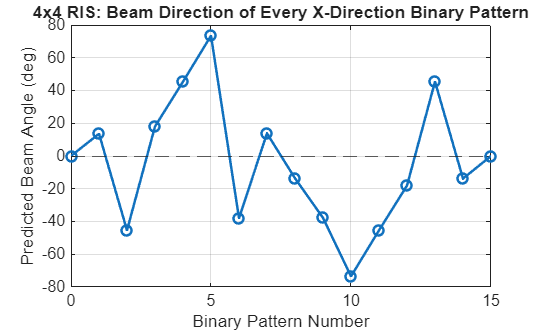


%% ============================================================
% 8. PLOT BEAM ANGLE FOR EVERY PATTERN
% ============================================================

figure( ...
    'Name','4x4 Binary Steering Codebook', ...
    'Position',[100 100 900 550]);

plot( ...
    0:numPatterns-1, ...
    allBeams, ...
    'o-', ...
    'LineWidth',1.5);

grid on;

xlabel('Binary Pattern Number');
ylabel('Predicted Beam Angle (deg)');

title('4x4 RIS: Beam Direction of Every X-Direction Binary Pattern');

yline(0,'--');

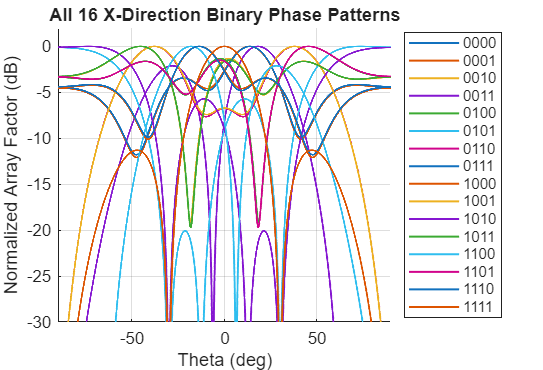


%% ============================================================
% 9. SHOW ALL RADIATION PATTERNS
% ============================================================

figure( ...
    'Name','All 16 Binary Patterns', ...
    'Position',[100 100 1100 750]);

hold on;
grid on;

for p = 1:numPatterns

    plot( ...
        theta, ...
        allPatterns_dB{p}, ...
        'LineWidth',1.2, ...
        'DisplayName',sprintf( ...
        '%d%d%d%d', ...
        allPatterns{p}(1,1), ...
        allPatterns{p}(1,2), ...
        allPatterns{p}(1,3), ...
        allPatterns{p}(1,4)));

end

xlabel('Theta (deg)');
ylabel('Normalized Array Factor (dB)');

title('All 16 X-Direction Binary Phase Patterns');

xlim([-90 90]);
ylim([-30 2]);

legend('Location','eastoutside');


%% ============================================================
% 10. HIGHLIGHT THE USEFUL PATTERNS
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('            MOST USEFUL STEERING STATES\n');

            MOST USEFUL STEERING STATES


fprintf('============================================================\n');


% Sort by absolute beam angle
[~,idxUseful] = sort(abs(allBeams),'ascend');

fprintf('\nClosest to broadside:\n');


Closest to broadside:



for q = 1:min(5,numPatterns)

    p = idxUseful(q);

    config = allPatterns{p};

    fprintf( ...
        '%d%d%d%d  -> %+7.2f deg\n', ...
        config(1,1), ...
        config(1,2), ...
        config(1,3), ...
        config(1,4), ...
        allBeams(p));

end

0000  ->   +0.00 deg
1111  ->   +0.00 deg
0001  ->  +13.60 deg
1000  ->  -13.60 deg
0111  ->  +13.77 deg



fprintf('\nLargest positive steering:\n');


Largest positive steering:



[~,idxPositive] = max(allBeams);

config = allPatterns{idxPositive};

fprintf( ...
    '%d%d%d%d -> %+7.2f deg\n', ...
    config(1,1), ...
    config(1,2), ...
    config(1,3), ...
    config(1,4), ...
    allBeams(idxPositive));

0101 ->  +73.47 deg



fprintf('\nLargest negative steering:\n');


Largest negative steering:



[~,idxNegative] = min(allBeams);

config = allPatterns{idxNegative};

fprintf( ...
    '%d%d%d%d -> %+7.2f deg\n', ...
    config(1,1), ...
    config(1,2), ...
    config(1,3), ...
    config(1,4), ...
    allBeams(idxNegative));

1010 ->  -73.47 deg



fprintf('\n');
fprintf('============================================================\n');

fprintf('                 END OF CODEBOOK STUDY\n');

                 END OF CODEBOOK STUDY


fprintf('============================================================\n');